# Fit of baseline and phase corrected data from 2021-06-28

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder1 = 'D:\Profile\qse\Files\_EDMRoC pinSC\20210628';
load([Opt.LFolder1, '\cwEDMR_2021_06_28.mat']);
[~, ncw] = size(x);

#### Fit

SysDb = struct(g = [2.0079 2.0061 2.0034], ...
    gStrain = [0.0054 0.0022 0.0018], ...
    lw = [0.005 1.389], ...
    Nucs = 'Si', A = [151 269]);
VaryDb = struct( ...
    lw = SysDb.lw);

SysV = struct(g = 2.01, ...
    gStrain = 0.0098, ...
    lw = [0. 0.526], ...
    weight = 0.54);
VaryV = struct( ...
    lw = SysV.lw, ...
    weight = SysV.weight);

SysC = struct(g = 2.0044, ...
    lw = [0 0.5], ...
    weight = 0.3);
VaryC = struct(...
    lw = SysC.lw, ...
    weight = SysC.weight);

SysTE = struct(g = 2.0077, ...
    gStrain = 0.0036, ...
    lw = [18.1 0], ...
    weight = 1);
VaryTE = struct(...
    lw = SysTE.lw, ...
    weight = SysC.weight);

Exp.mwFreq = 9.6055875; % GHz

Sys = {SysDb, SysV};
Vary = {VaryDb, VaryV};

% esfit(y(:, icw), @pepper, {Sys, Exp}, {Vary})

wbar = waitbar(0, 'Performing least-square fitting', ...
    'Name', 'esfit in progress');
for icw = 1:ncw
    x_ = x(:, icw); y_ = y(:, icw);
    Exp.Range = [min(x_) max(x_)];
    Fit_ = esfit(y_, @pepper, {Sys, Exp}, {Vary})
    if icw == 1
        Fit = repmat(Fit_, 1, ncw);
    else
        Fit(icw) = Fit_;
    end
    waitbar(icw/ncw, wbar)
end

-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepper
Number of fit parameters: 4
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 4 active parameters...
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   1: value 2.23152e-02   edge 1.00000e-01   initial simplex
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   2: value 2.23152e-02   edge 2.77800e-01   reflection
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
itera

Fit_ = struct with fields:
              pfit: [4×1 double]
            pnames: {4×1 cell}
         pfit_full: [4×1 double]
           argsfit: {{1×2 cell}  [1×1 struct]}
              pstd: [4×1 double]
              ci95: [4×2 double]
               cov: [4×4 double]
              corr: [4×4 double]
           p_start: [4×1 double]
            fitraw: [1024×1 double]
               fit: [1024×1 double]
             scale: 0.0030
          baseline: [1024×1 double]
              mask: [1024×1 logical]
         residuals: [1024×1 double]
               ssr: 0.4517
              rmsd: 0.0210
    bestfithistory: [1×1 struct]


-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepper
Number of fit parameters: 4
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 4 active parameters...
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   1: value 2.50072e-02   edge 1.00000e-01   initial simplex
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   2: value 2.50072e-02   edge 1.73625e-01   contraction insi

Fit_ = struct with fields:
              pfit: [4×1 double]
            pnames: {4×1 cell}
         pfit_full: [4×1 double]
           argsfit: {{1×2 cell}  [1×1 struct]}
              pstd: [4×1 double]
              ci95: [4×2 double]
               cov: [4×4 double]
              corr: [4×4 double]
           p_start: [4×1 double]
            fitraw: [1024×1 double]
               fit: [1024×1 double]
             scale: 0.0040
          baseline: [1024×1 double]
              mask: [1024×1 logical]
         residuals: [1024×1 double]
               ssr: 0.5540
              rmsd: 0.0233
    bestfithistory: [1×1 struct]


-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepper
Number of fit parameters: 4
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 4 active parameters...
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   1: value 2.39426e-02   edge 1.00000e-01   initial simplex
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   2: value 2.39426e-02   edge 1.73625e-01   contraction insi

Fit_ = struct with fields:
              pfit: [4×1 double]
            pnames: {4×1 cell}
         pfit_full: [4×1 double]
           argsfit: {{1×2 cell}  [1×1 struct]}
              pstd: [4×1 double]
              ci95: [4×2 double]
               cov: [4×4 double]
              corr: [4×4 double]
           p_start: [4×1 double]
            fitraw: [1024×1 double]
               fit: [1024×1 double]
             scale: 0.0035
          baseline: [1024×1 double]
              mask: [1024×1 logical]
         residuals: [1024×1 double]
               ssr: 0.5427
              rmsd: 0.0230
    bestfithistory: [1×1 struct]


-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepper
Number of fit parameters: 4
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 4 active parameters...
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   1: value 2.92016e-02   edge 1.00000e-01   initial simplex
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   2: value 2.92016e-02   edge 1.73625e-01   contraction insi

Fit_ = struct with fields:
              pfit: [4×1 double]
            pnames: {4×1 cell}
         pfit_full: [4×1 double]
           argsfit: {{1×2 cell}  [1×1 struct]}
              pstd: [4×1 double]
              ci95: [4×2 double]
               cov: [4×4 double]
              corr: [4×4 double]
           p_start: [4×1 double]
            fitraw: [1024×1 double]
               fit: [1024×1 double]
             scale: 0.0047
          baseline: [1024×1 double]
              mask: [1024×1 logical]
         residuals: [1024×1 double]
               ssr: 0.8548
              rmsd: 0.0289
    bestfithistory: [1×1 struct]


delete(wbar)

% figure()
% plot(x_, y_)
% hold on
% plot(x_, Fit1.fit)
% plot(x_, y_ - Fit1.fit, 'Color', [0 0 0])

% figure()
% plot(x(:, icw), y(:, icw))
% hold on
% plot(x(:, icw), scaleY(pepper(Sys, Exp), y(:, icw)))
% plot(x(:, icw), scaleY(pepper(Sys, Exp), y(:, icw)))
% % plot(x(:, icw), scaleY(pepper(Sys2, Exp), y(:, icw)))
% % plot(x(:, icw), scaleY(pepper(Sys, Exp) + pepper(Sys1, Exp) + pepper(Sys2, Exp), y(:, icw)))
% legend('data','-','1','2', 'sum')

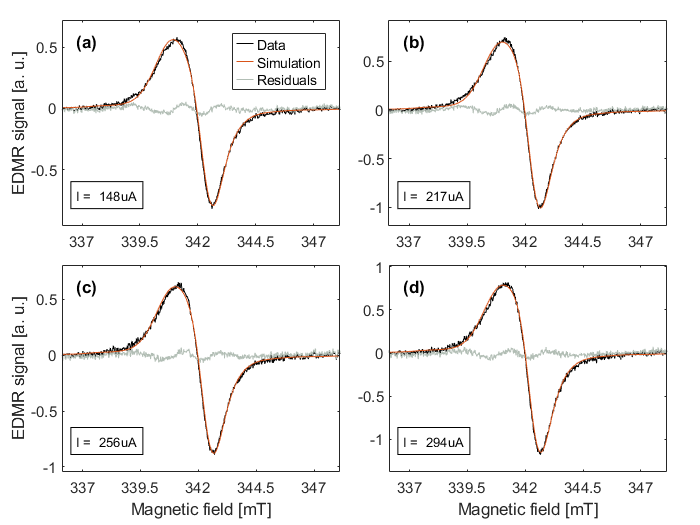

grayC = '#b2beb5';
% ID (V and uA): (1.1 148), (1.2 217), (1.25 256), (1.3 294)
subplotID = ["(a)", "(b)", "(c)", "(d)"];
LineW = 0.8;
figure()
tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact')
for icw = 1:ncw
    nexttile
    h(1) = plot(x(:, icw), y(:, icw), 'Color', [0 0 0]);
    hold on
    h(2) = plot(x(:, icw), Fit(icw).fit);
    h(3) = plot(x(:, icw), y(:, icw) - Fit(icw).fit, 'Color', grayC);
    
    set(gca,'Children',[h(2) h(3) h(1)]) % [top, middle, bottom]
    set(gca, "Layer", "top")

    xticks(337:2.5:347); yticks(-1:0.5:1);
    xlim(setAxLim(x(:, icw), 0)); ylim(setAxLim(y(:, icw), 0.1));

    if icw == ncw - 3 || icw == ncw - 1
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > ncw - 2
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end

    IDidx = icw - ncw + 4;
    text(0.05, 0.9, subplotID(IDidx), 'Units', 'normalized', ...
        'FontWeight', 'bold', ...
        'FontSize', 10)
    % title(cw(icw).Title)
    annStr = {sprintf('I = %s', cwStruct(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');

    if icw == 1
        lgd = legend([h(1) h(2) h(3)],{'Data', 'Simulation', 'Residuals'});
        lgd.ItemTokenSize = [10 10 10];
        lgd.Location = 'NorthEast';
    end
end
exportStr = input('Export graphics? y/n\n', 's');
if strcmp(exportStr, 'y')
    Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
    exportgraphics(gcf, [Opt.SFolder, '/2021-06-28 cwEDMR fit.png'])
else
    disp('Graphics not exported')
end

#### "DeltaI"/I is not constant

Idc = [148 217 256 294]; % uA
figure('Visible', 'off')
hold on
for icw = 1:ncw
    plot(x(:, icw), y(:, icw)/Idc(icw))
end